# example

s=tf('s');

Transfer function:

G=(s+2)/(s^2+2*s+3);

The product of two transfer functions is obtained by:

G12 = G1 * G2;

For a system with 2 inputs and 2 outputs, the closed-loop transfer matrix is obtained

with

S=feedback(eye(2),G*F);
T=feedback(G*F,eye(2));

For a SISO system this can be written:

S=1/(1+G*F);
T=G*F/(1+G*F);

For numerical reasons it is very important to use the function minreal, for example

minreal(T). This creates an equivalent system where all canceling pole/zero pair,

corresponding to unobservable or uncontrollable states, are eliminated.

The bode diagram for G is plotted by typing:

bode(G);

OR:

bode(G,{wmin,wmax});

Amplitude and phase at a given frequency are obtained by:

[m,p]=bode(G,w);

Phase margin, amplitude margin and corresponding frequencies are obtained by:

[Gm,Pm,wp,wc]=margin(G*F);

To simulate a step response in the control signal, use the function:

step(G);

OR:

step(G,tfinal);

In the same way, to simulate a step response in the reference signal, we type:

step(T);


# 4.1

## 4.1.1

s=tf('s');
G = (3*(-s+1))/((5*s+1)*(10*s+1));

w_cd = 0.4;
[m,p] = bode(G,w_cd);
p_margin = -180 + p; 
p_d = 30;
p_lag = 6;
p_max = p_d-p_margin + p_lag;

beta = 0.5455;
t_d = 1/(w_cd*sqrt(beta));

%G_abs = sqrt(3^2+(3*0.4)^2)/sqrt((1-50*0.4^2)^2+(15*0.4)^2)
K = sqrt(beta)/m;
t_i = 10/w_cd;
gamma = 0;

F_lead = ((t_d*s+1)/(beta*t_d*s+1));
F_lag = ((t_i*s+1)/(t_i*s+gamma));
F=K*F_lead*F_lag;

T=G*F/(1+G*F);
T=minreal(T);

%step(T,70)
%bode(F*G)

[Gm,Pm,wp,wc]=margin(G*F);


## 4.1.2

G_c = minreal(F*G/(1+F*G));
bode(G_c)
step(G_c)

Bandwidth:

w_b = 0.77 rad/s

Resonance peak:

M_T = 6.36 dB at w_r = 0.45 rad/s

Overshot:

40%

Rise time:

2.39 s

## 4.1.3

beta = 0.246;
t_d = 1/(w_cd*sqrt(beta));
K = sqrt(beta)/m;

F_lead = ((t_d*s+1)/(beta*t_d*s+1));
F_lag = ((t_i*s+1)/(t_i*s+gamma));
F=K*F_lead*F_lag;

[Gm,Pm,wp,wc]=margin(G*F);

G_c = F*G/(1+F*G);
bode(G_c)
step(G_c)


Bandwidth:

w_b = 0.92 rad/s

Resonance peak:

M_T = 2.24 dB at w_r = 0.54 rad/s

Overshot:

12%

Rise time:

2.4 s

# 4.2

## 4.2.1

The exercise is about designing F r and F y in Figure 2 such that:

• The rise time for a step change in the reference signal less than 0.2 s and the

   overshoot is less than 10%.

• For a step in the disturbance, |y(t)| ≤ 1 ∀t and |y(t)| ≤ 0.1 for t > 0.5 s.

• Since the signals are scaled, the control signal obeys |u(t)| ≤ 1 ∀t.

s=tf('s');
G=20/((s+1)*((s/20)^2+s/20 +1));
Gd=10/(s+1);
[Gm,Pm,wp,wc]=margin(Gd);
Fy=minreal(wc/(G*s));

According to the bode diagram for frequencies above approx 10  rad/s control action is needed. 

Transfer function (closed) from d to y:

Gdc=minreal(Gd/(1+G*Fy))


Gdc =
 
          10 s
  ---------------------
  s^2 + 10.95 s + 9.947
 
Continuous-time transfer function.



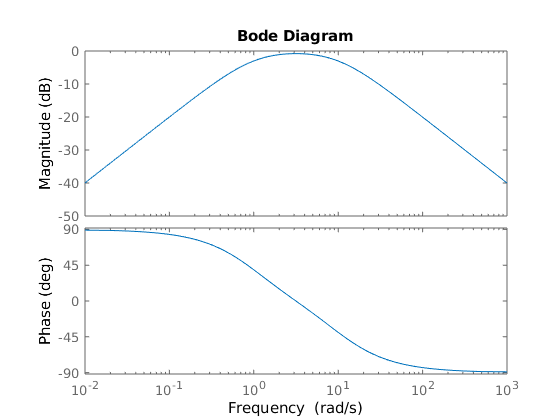

bode(Gdc)

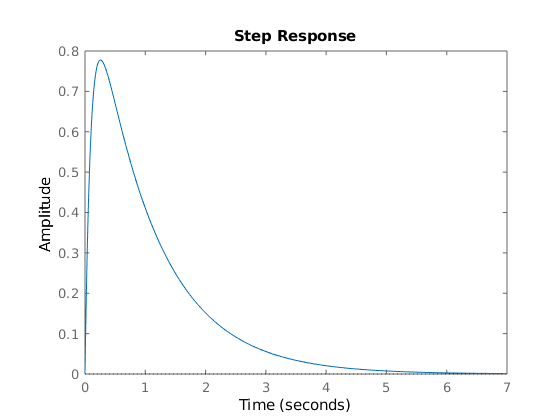

step(Gdc)

Higher degree in the numerator than the degree of the denominator suggest Fy is not a proper controller. Two more poles have to be added.

Creating poles:

pole1=10*wc;
pole2=10*wc;

Adding poles in a way that does ***not *** affect low frequencies. Plotting the bode diagram for the proper controller (with extra poles)

Fy_proper=minreal((Fy*pole1*pole2)/((s+pole1)*(s+pole2)))


Fy_proper =
 
  12.3 s^3 + 258.4 s^2 + 5167 s + 4921
  ------------------------------------
        s^3 + 198.9 s^2 + 9895 s
 
Continuous-time transfer function.



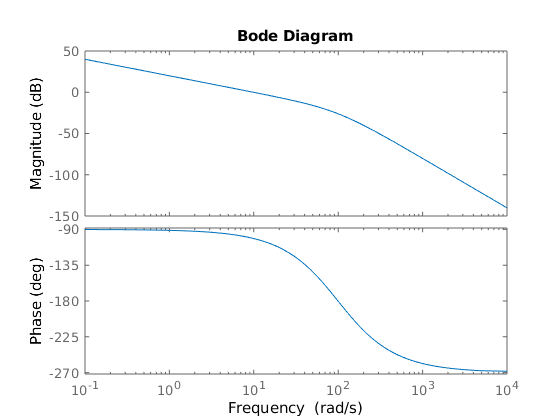

bode(Fy_proper*G)

[Gm,Pm,wp,wc]=margin(Fy_proper*G);

## 4.2.2